close all;
clear all;
rosshutdown;

Shutting down global node /matlab_global_node_81248 with NodeURI http://10.0.1.54:55754/


ip_TurtleBot = '10.0.1.57';    
ip_Matlab = '10.0.1.54'; 

setenv('ROS_MASTER_URI', strcat('http://', ip_TurtleBot,':11311'))
setenv('ROS_IP', ip_Matlab)

rosinit(ip_TurtleBot)

The value of the ROS_IP environment variable, 10.0.1.54, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_90042 with NodeURI http://10.0.1.54:55786/



TurtleBot_Topic.picam = "/raspicam_node/image/compressed";
image_sub = rossubscriber(TurtleBot_Topic.picam);


global focalLength;
global pixelSize;
global cameraHeight;
global centerPixel;
global leftColumnCrop;
global rightColumnCrop;
global upperRowCrop;
global lowerRowDrop;
%all units in mm or pixels
focalLength = 3.6;
pixelSize = 0.00567; %actual pixel size is 1.4microns, this is effective pixel size of compressed image
cameraHeight = 130;
centerPixel = [240, 320];
leftColumnCrop = 0;
rightColumnCrop = 640;
upperRowCrop = 360;
lowerRowDrop = 480;

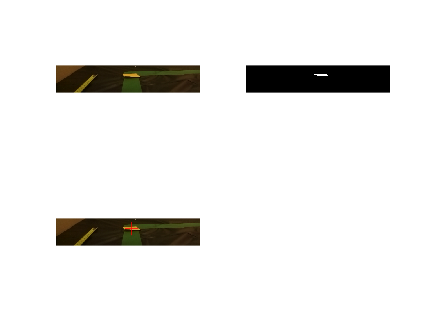

image = grabAndCleanUpImage(image_sub);
%image = imread('YellowTarget.png');
figure
subplot(221); imshow(image)
yellowImage = GetYellowPoints(image);
centroid = GetYellowCentroid(yellowImage);
subplot(223); imshow(image); hold on
plot(centroid(2), centroid(1), '+', 'MarkerSize', 10, 'Color',[1 0 0])
hold off

distanceComponents = CalcObjectDistance(centroid)

distanceComponents =    14.2683  503.2907


%130mm camera to ground distance
%350mm distance away


Performing LDA on example target images

myFolder = 'E:\School\ECE588\Repo\targetImages';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);


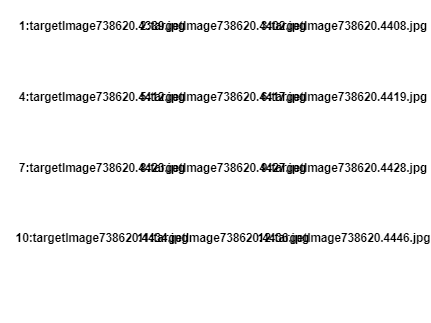

figure
for j=1:length(jpegFiles)
    subplot(4,3,j); imshow(imread(strcat(jpegFiles(j).folder, '\', jpegFiles(j).name)))
    title(strcat(string(j), ': ', jpegFiles(j).name));
end

%x,y (col,row)
image1point1 = [268,249];
image1point2 = [322,293];
image2point1 = [204,297];
image2point2 = [389,449];
image3point1 = [305,173];
image3point2 = [344,202];
image4point1 = [295,1];
image4point2 = [467,129];
image5point1 = [254,208];
image5point2 = [316,270];
image6point1 = [196,166];
image6point2 = [371,331];
image7point1 = [313,230];
image7point2 = [338,256];
image8point1 = [358,260];
image8point2 = [397,290];
image9point1 = [173,189];
image9point2 = [281,279];
image10point1 = [276,243];
image10point2 = [318,276];
image11point1 = [311,236];
image11point2 = [330,254];
image12point1 = [260,205];
image12point2 = [276,236];
imageBoundingBoxes = [[image1point1,image1point2];[image2point1,image2point2];[image3point1,image3point2];[image4point1,image4point2];[image5point1,image5point2];[image6point1,image6point2];[image7point1,image7point2];[image8point1,image8point2];[image9point1,image9point2];[image10point1,image10point2];[image11point1,image11point2];[image12point1,image12point2]];

eigenValues = [];
eigenVectors = [];
for j=1:length(jpegFiles)
    thisImage = imread(strcat(jpegFiles(j).folder, '\', jpegFiles(j).name));
    rowMin = imageBoundingBoxes(j,1);
    rowMax = imageBoundingBoxes(j,3);
    colMin = imageBoundingBoxes(j,2);
    colMax = imageBoundingBoxes(j,4);
    [secondLargestEigenValue, secondLargestEigenVector] = TrainLDA(rowMax, rowMin, colMax, colMin, thisImage);
    eigenValues = [eigenValues, secondLargestEigenValue];
    eigenVectors = [eigenVectors, secondLargestEigenVector];
end

function image = grabAndCleanUpImage(image_sub)
    global leftColumnCrop;
    global rightColumnCrop;
    global upperRowCrop;
    global lowerRowDrop;
    image_compressed = receive(image_sub);
    image_compressed.Format = 'bgr8; jpeg compressed bgr8';
    rotatedImage = imrotate(readImage(image_compressed), 180);
    %eliminate the upper half of the image
    image = imcrop(rotatedImage, [leftColumnCrop, upperRowCrop, rightColumnCrop, lowerRowDrop]);
end

function yellowPoints = GetYellowPoints(originalImage)
    redLowerBound =200;% 
    redUpperBound =220;%
    greenLowerBound =145;% 
    greenUpperBound =160;%
    blueLowerBound =35;% 
    blueUpperBound =55;% 
    yellowPoints = redUpperBound>=originalImage(:,:,1) & originalImage(:,:,1)>=redLowerBound & originalImage(:,:,2)<=greenUpperBound & originalImage(:,:,2)>=greenLowerBound & originalImage(:,:,3)<=blueUpperBound & originalImage(:,:,3)>=blueLowerBound;
    subplot(222); imshow(yellowPoints)
end

function centroid = GetYellowCentroid(binaryImage)
    [y, x] = find(binaryImage);
    yMean = mean(y);
    xMean = mean(x);
    centroid = [round(yMean), round(xMean)];
end

function distanceComponents = CalcObjectDistance(centroidPixelPosition)
    global focalLength;
    global pixelSize;
    global cameraHeight;
    global centerPixel;
    global upperRowCrop;
    centroidPixelPositionYSigned = centroidPixelPosition(1) + upperRowCrop - (centerPixel(1));
    centroidPixelPositionXSigned = centroidPixelPosition(2) - (centerPixel(2));
    yPrime = pixelSize*centroidPixelPositionYSigned;
    xPrime = pixelSize*centroidPixelPositionXSigned;
    z = cameraHeight * focalLength / yPrime;
    x = xPrime * z / focalLength;
    distanceComponents = [x, z];
end

%call this for each image with the target in it and labeled
%get the average eigen value / vector for each image and use that for the
%real thing
function [secondLargestEigenValue, secondLargestEigenVector] = TrainLDA(rowMax, rowMin, colMax, colMin, originalImage)
    pimg = double(originalImage(rowMin:rowMax,colMin:colMax,:)); %Select a pillar patch
    v12 = cov(pimg(:,:,1), pimg(:,:,2));
    v13 = cov(pimg(:,:,1), pimg(:,:,3));
    v23 = cov(pimg(:,:,2), pimg(:,:,3));
    
    v = [v12(1,1) v12(1,2) v13(1,2);
        v12(2,1) v12(2,2) v23(1,2);
        v13(2,1) v23(2,1) v23(2,2)];
    [ev,lv]=eig(v);
    %Get second largest eigen value and corresponding eigen vector
    sortedEigenValues = sort(max(lv));
    secondLargestEigenValue = sortedEigenValues(2);
    secondLargestEigenVectorLocation = find(max(lv)==secondLargestEigenValue);  %find the column number of second largest eigen value
    secondLargestEigenVector = ev(:,secondLargestEigenVectorLocation);
end